Suponha uma barra de cobre de comprimento $L$ que está lateralmente isolada e tem uma temperatura inicial $u_0$. Suponha que o topo da barra ($x = 0$) é isolada, enquanto a parte mais baixa ($y = L$) está imersa em uma  água em movimento com uma temperatura constante.

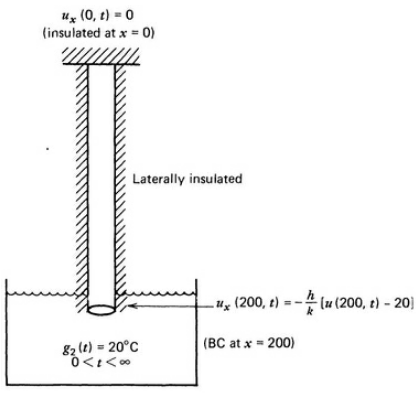

clearvars;clc;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

Coeficientes de difusividade, condutividade, troca de calor entre meios e temperatura ambinete

gamma = 0.1;
alpha = sqrt(gamma);
k = 0.5;
h = 2;
L = 3;
uAmb = 20;

A fronteira $x=0$ está isolada. Não há fluxo de calor saindo ou entrando nela. 

A fronteira $x=L$ troca calor livremente com o meio ambiente.

A temperatura da barra em $t=0$ é $0$ ao longo de toda a barra ($\mathrm{u}\left(x,0\right)=0$).

### Solução:

Imaginando a solução como a multiplicação de duas funções, uma como função somente do tempo e outra somente da posição ($$${\mathop{\rm u}\nolimits} (x,t){\rm{ }} = {\rm{ }}{\mathop{\rm X}\nolimits} (x) \;{\mathop{\rm T}\nolimits} (t)$$$), faz-se o que chama-se de método da separação de variáveis e encontrar a solução

Susbstituindo a solução na EDP da difusão $\[{\rm{X}}\,{\rm{T'}} = {\alpha ^2}\,{\rm{X''}}\,{\rm{T}}\]$ e rearranjando $\[\frac{{{\rm{T'}}}}{{{\alpha ^2}\;{\rm{T}}}} = \frac{{{\rm{X''}}}}{{\rm{X}}}\]$. Esta igualdade só é possível quando ambas as divisões são igual a uma constante. A única constante que faz sentido físico é uma de sinal negativo. Assim escreve-se $\[\frac{{{\rm{T'}}}}{{{\alpha ^2}\,{\rm{T}}}} = \frac{{{\rm{X''}}}}{{\rm{X}}} =  - {\lambda ^2}\]$.

Resolvendo cada equação de maneira independente chega-se às soluções:

- 
$$\[\left\{ {\begin{array}{*{20}{l}}
{{\rm{T}}\left( t \right)}& = &{{\mathop{\rm C}\,\nolimits} {{\rm{e}}^{ - {\alpha ^2}{\lambda ^2}t}}}\\
{{\rm{X}}\left( x \right)}& = &{{\mathop{\rm A}\nolimits} \cos \left( {\lambda \, t} \right) + {\mathop{\rm B}\nolimits} \sin \left( {\lambda \, t} \right)}
\end{array}} \right.\]$$


Agora escreve-se a solução da EDP como $\[{\rm{u}}\left( {x,t} \right) = {\rm{T}}\left( t \right){\mkern 1mu} {\kern 1pt} {\rm{X}}\left( x \right) = {{\rm{e}}^{ - {\alpha ^2}{\lambda ^2}t}}{\mkern 1mu} {\kern 1pt} \left[ {{\mathop{\rm A}\nolimits} \sin \left( {\lambda \,x} \right) + {\mathop{\rm B}\nolimits} \cos \left( {\lambda \,x} \right)} \right]\]$.

Não faz sentido fazer $\[{\rm{C}}\,{\rm{A}}\]$ e $\[{\rm{C}}\,{\rm{A}}\]$ multiplicar os termos $\sin$ e $\cos$, por isto deixa-se apenas $\[{\rm{A}}\]$ e $\[{\rm{B}}\]$. Estas são descobertas a partir das condições de fronteira e inicial.

Além disto, existem infinitos $\lambda$, e consequentemente infinitos $\rm A$ e $\rm B$ correspondentes que satisfazem a solução. Do conhecimento clássico de EDPs é solução a combinação linear destas funções:


$$\[\sum\limits_{n = 1}^\infty  {{\rm{u}}\left( {x,t} \right) = \sum\limits_{n = 1}^\infty  {{{\rm{e}}^{ - {\alpha ^2}{\lambda _n}^2t}}{\mkern 1mu} {\kern 1pt} {\kern 1pt} \left[ {{{\rm{A}}_n}\sin \left( {{\lambda _n}x} \right) + {{\rm{B}}_n}\cos \left( {{\lambda _n}x} \right)} \right]} } \]$$


#### Condições de fronteira

Utiliza-se a função derivada em ambas as condições de fronteira.

É derivada da função ${\rm{u}}\left( {x,t} \right)$, $\[{{\rm{u}}_x}\left( {x,t} \right) = {{\rm{e}}^{ - {\alpha ^2}{\lambda ^2}t}}{\mkern 1mu} {\kern 2pt} 
\left[ {\lambda\, {\mathop{\rm A}\nolimits} \cos \left( {\lambda \,x} \right) + \lambda\, {\mathop{\rm B}\nolimits} \sin \left( {\lambda \,x} \right)} \right]\]$. 

A fronteira $x=L$ está isolada. Não há fluxo de calor saindo ou entrando nela, o que nos faz escrever para a condução de calor nesta fronteira

 $-k\;{\mathrm{u}}_x \left(L,t\right)=0$ (Condição de Neumann).

$\[\begin{array}{*{20}{l}}
{{{\rm{e}}^{ - {\alpha ^2}{\lambda ^2}t}}\left[ {{\rm{A}}\lambda \cos \left( {\lambda L} \right) - {\rm{B}}\lambda \sin \left( {\lambda L} \right)} \right] = 0}\\
{{\rm{A}}\cos \left( {\lambda L} \right) = {\rm{B}}\sin \left( {\lambda L} \right)}
\end{array}\]$    (1)

A fronteira $x=0$ há troca calor livremente com o ambiente externo, sendo o fluxo de calor  saindo ou entrando na barra dado pela expressão de conservação de fluxo 

$\[ - k{\mkern 1mu} {\kern 1pt} {\kern 1pt} {{\rm{u}}_x}\left( {0,t} \right) =  - h\:{\rm{u}}\left( {0,t} \right)\]$  (Condição de Robin).

$\[\begin{array}{l}
k\,{\mkern 1mu} {\kern 1pt} {\kern 1pt} \left[ {{e^{ - {\lambda ^2}{\alpha ^2}t}}\left( { - {\rm{A}}\,\lambda \sin \left( 0 \right) + {\rm{B}}\,\lambda \cos \left( 0 \right)} \right)} \right] = h\:\left[ {{e^{ - {\lambda ^2}{\alpha ^2}t}}\left( {{\rm{A}}\,\cos \left( 0 \right) + {\rm{B}}\,\sin \left( 0 \right)} \right)} \right]\\
k{\mkern 1mu} \,{\kern 1pt} {\kern 1pt} \left( {{\rm{B}}\,\lambda } \right) = h\:\left( {{\rm{A}}\,} \right)\\
{\rm{A}} = {\rm{B}}\frac{k}{h}\lambda 
\end{array}\]$    (2)

Substituinto em (1)

$\[\begin{array}{l}
{\rm{B}}\frac{k}{h}\lambda \cos \left( {\lambda L} \right) = {\rm{B}}\sin \left( {\lambda L} \right)\\
\frac{k}{h}\lambda \cos \left( {\lambda L} \right) = \sin \left( {\lambda L} \right)
\end{array}\]$    (3)

Existem infinitos $\lambda$ que satisfasem a solução

Número de $\lambda$ a enconrar

nl = 50;

Função que desejamos encontrar as raízes $\[{\rm{func}}\left( {{\lambda _n}} \right) = h{\mkern 1mu} \cos \left( {{\lambda _n}{\mkern 1mu} L} \right) - k{\mkern 1mu} {\lambda _n}{{\rm{B}}_n}{\mkern 1mu} {\rm{sin}}\left( {{\lambda _n}{\mkern 1mu} L} \right)\]$

per = 2*pi/L;

período de uma função trigonomérica é de $2\,\pi$.

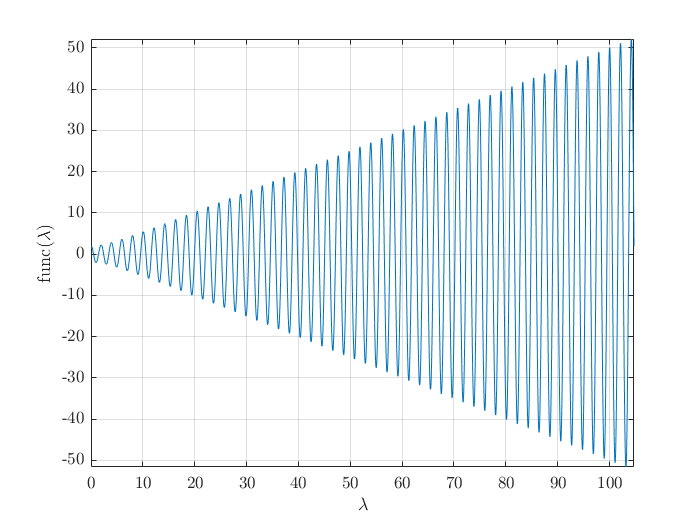

func = @(ln) h.*cos(ln.*L) - ln.*k.*sin(ln.*L);
fplot(func,[0,nl*per]); grid; drawnow;
xlabel('$\lambda$'); 
ylabel('func($\lambda$)');

As raízes serão encontradas em intervalos $\[\left[ {{w_l},{w_u}} \right]\]$. O primeiro intervalo está entre $\[\left( {0,\pi } \right)\]$.

wl = 0;

Início do contador

i = 1;

Definindo o tamanho do vetor $\lambda$, pois isto agiliza a simulação.

lbd(1:nl) = 0;

Encontrando as `nl` primeiras constantes de integração.

while( i <= nl )
    wu = wl + per/2-0.1; % limite superior para procurar a raiz
    lbd(i) = fzero(func,[wl,wu]); % zero da função
    wl = lbd(i)+0.1; % próximo limite inferior
    i = i + 1;
end
(lbd)

lbd =     0.4835    1.4545    2.4357    3.4290    4.4335    5.4471    6.4678    7.4938    8.5238    9.5569   10.5923   11.6296   12.6683   13.7082   14.7490   15.7907   16.8329   17.8757   18.9190   19.9627   21.0067   22.0510   23.0955   24.1403   25.1852   26.2304   27.2757   28.3211   29.3667   30.4123   31.4581   32.5039   33.5499   34.5959   35.6420   36.6881   37.7343   38.7806   39.8269   40.8732   41.9196   42.9660   44.0125   45.0590   46.1055   47.1521   48.1987   49.2453   50.2919   51.3386


#### Condições iniciais

Para encontrar $\[{\mathop{\rm B}\nolimits} \]$ recorremos à condição inicial $u(x,0)$, não esquecendo que precisamos diminuí-la de $u_{\rm amb}$.


$$\[ - 20 = \sum\limits_{n = 1}^\infty  {{{\rm{A}}_n}\,\cos \left( {{\lambda _n}x} \right) + {{\rm{B}}_n}\,\sin \left( {{\lambda _n}x} \right)} \]$$



$$\[{{\rm{A}}_n} = \frac{{2{\lambda _n}}}{{{\lambda _n}L - \sin \left( {{\lambda _n}L} \right)\cos \left( {{\lambda _n}L} \right)}}\int\limits_0^L {{\rm{u}}\left( {x,0} \right)\sin \left( {{\lambda _n}x} \right){\rm{d}}x} \]$$



$$\[{{\rm{B}}_n} = \frac{{2{\lambda _n}}}{{{\lambda _n}L + \sin \left( {{\lambda _n}L} \right)\cos \left( {{\lambda _n}L} \right)}}\int\limits_0^L {{\rm{u}}\left( {x,0} \right)\cos \left( {{\lambda _n}x} \right){\rm{d}}x} \]$$


syms xi x
IC(x) = -20*x/x

$$IC(x) = -20$$

IC = matlabFunction(IC);
A(1:nl) = 0;
B(1:nl) = 0;
for i=1:length(lbd)
    l = lbd(i);


$$\[{{\rm{A}}_n} = \frac{{2{\lambda _n}}}{{{\lambda _n}L - \sin \left( {{\lambda _n}L} \right)\cos \left( {{\lambda _n}L} \right)}}\int\limits_0^L {{\rm{u}}\left( {x,0} \right)\sin \left( {{\lambda _n}x} \right){\rm{d}}x} \]$$


    A(i) = ( 2*l/(l*L-sin(l*L)*cos(l*L) ) * int( IC(xi)*sin(l*xi), 0, L ) );


$$\[{{\rm{B}}_n} = \frac{{2{\lambda _n}}}{{{\lambda _n}L + \sin \left( {{\lambda _n}L} \right)\cos \left( {{\lambda _n}L} \right)}}\int\limits_0^L {{\rm{u}}\left( {x,0} \right)\cos \left( {{\lambda _n}x} \right){\rm{d}}x} \]$$


    B(i) = ( 2*l/(l*L+sin(l*L)*cos(l*L) ) * int( IC(xi)*cos(l*xi), 0, L ) );
end
B

B =   -25.2994    8.0242   -4.4076    2.8169   -1.9420    1.4077   -1.0599    0.8226   -0.6547    0.5320   -0.4401    0.3696   -0.3145    0.2707   -0.2353    0.2063   -0.1823    0.1622   -0.1453    0.1308   -0.1184    0.1076   -0.0983    0.0901   -0.0829    0.0765   -0.0708    0.0657   -0.0612    0.0571   -0.0534    0.0500   -0.0470    0.0442   -0.0417    0.0394   -0.0372    0.0352   -0.0334    0.0317   -0.0302    0.0287   -0.0274    0.0261   -0.0250    0.0239   -0.0229    0.0219   -0.0210    0.0202


A

A =   -26.4389  -13.2765   -2.7972   -6.7431   -0.8046   -4.5537   -0.3155   -3.4119   -0.1504   -2.7159   -0.0820   -2.2505   -0.0492   -1.9189   -0.0317   -1.6713   -0.0216   -1.4797   -0.0153   -1.3271   -0.0112   -1.2028   -0.0085   -1.0997   -0.0066   -1.0127   -0.0052   -0.9385   -0.0042   -0.8743   -0.0034   -0.8184   -0.0028   -0.7691   -0.0023   -0.7254   -0.0020   -0.6864   -0.0017   -0.6514   -0.0014   -0.6198   -0.0012   -0.5910   -0.0011   -0.5649   -0.0009   -0.5409   -0.0008   -0.5189


Inicialização das variáveis recurssivas

X = 0;
T = 0;
u = 0;

Definição da malha de espaço e tempo

x = linspace(0,L,20);
t = linspace(0,20,20);
[x,t] = meshgrid(x,t);

Cálculo de todas as temperaturas pela função $\[{\rm{u}}\left( {x,t} \right) = {\rm{T}}\left( t \right){\rm{X}}\left( x \right) = \left[ {{{\rm{e}}^{ - {\alpha ^2}{\lambda ^2}t}}} \right]\left[ {{\rm{B}}\cos \left( {\lambda {\mkern 1mu} x} \right)} \right]\]$

for i=1:length(lbd)
    X = double( A(i)*sin(lbd(i)*x) + B(i)*cos(lbd(i)*x) );
    T = double( exp(-(lbd(i)*alpha)^2*t) );
    u = u + T.*X;
end

Somando a temperatura ambiente ou o valor de ${\rm B}_0$.

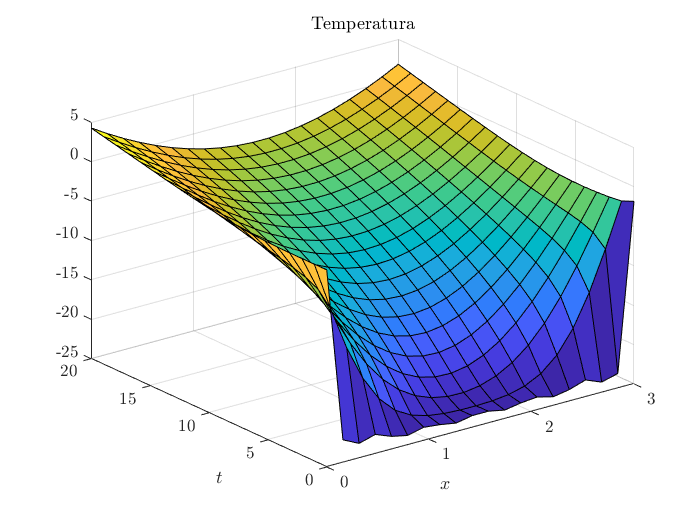

u = u + 20;
surf(x,t,u);
xlabel('$x$'); ylabel('$t$');
title('Temperatura')